fig = 0;

## Sampling theorem, aliasing

We will show what happens with the spectrum when the image is sampled. Then the image will be reconstructed from the sampled spectrum using the Shanon reconstruction filter. 

The procedure (sampling/reconstruction) will be repeated with increasing sampling factor, namely sampling by 2,4,8,16,32. You will see that it is possible to reconstruct the sampled image without artifacts when the condition of the Sampling Thorem holds. 

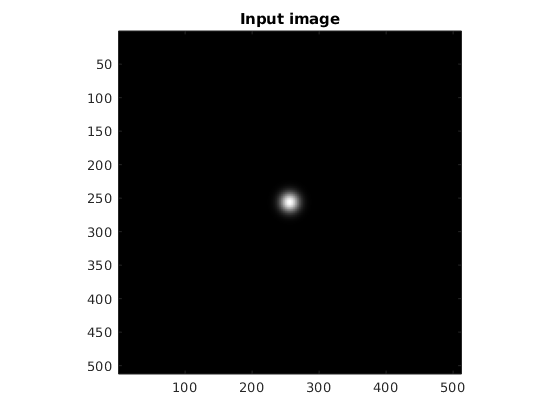

% input image 
x = image_generator('Gaussian', [512,512], 10);

% FFT of the input
X = fft2(x);

fig = fig+1; figure(fig);
imagesc(real(x)); colormap gray; axis image;
title('Input image')

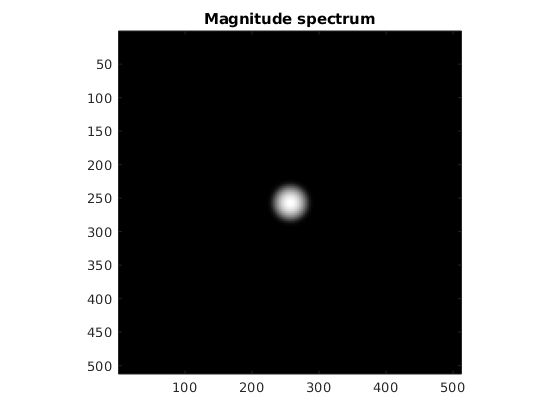


fig = fig+1; figure(fig); 
show_spectrum(X,'gray'); 
title('Magnitude spectrum');

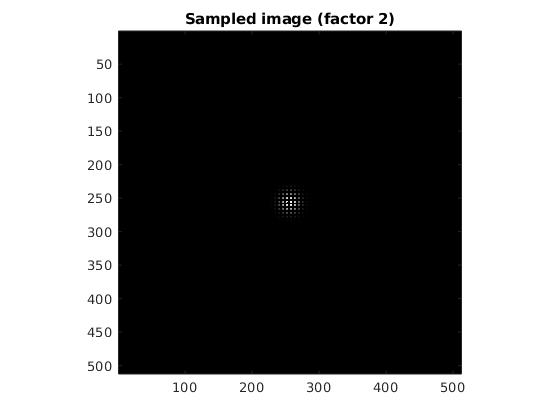

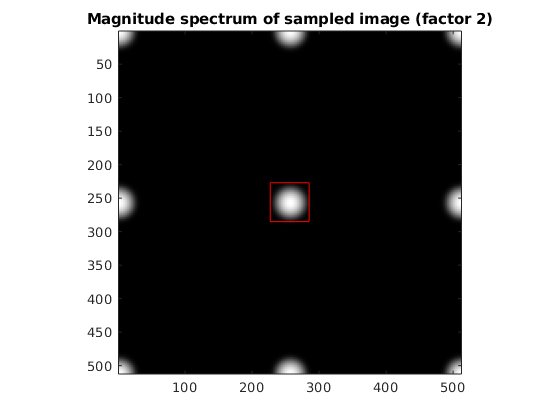

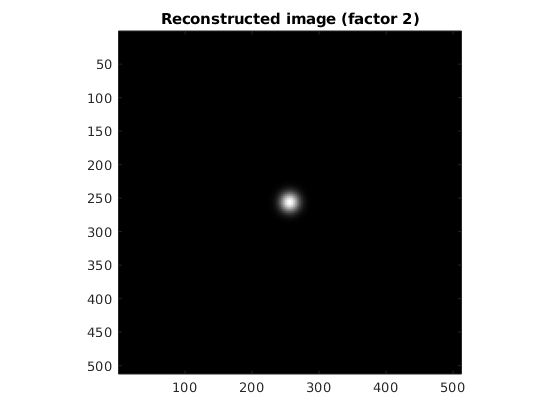

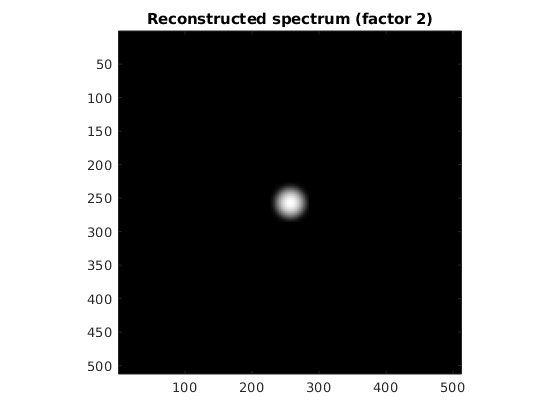

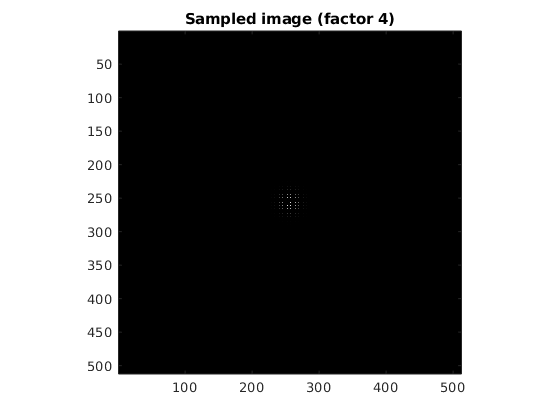

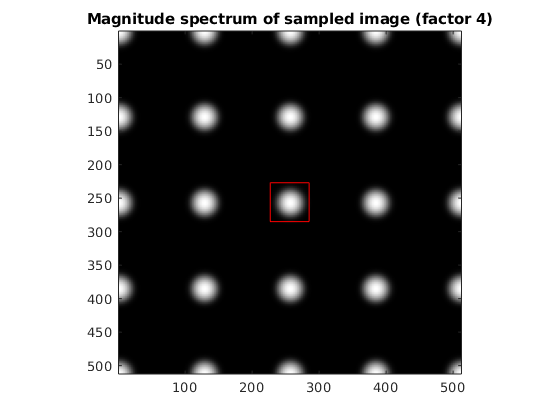

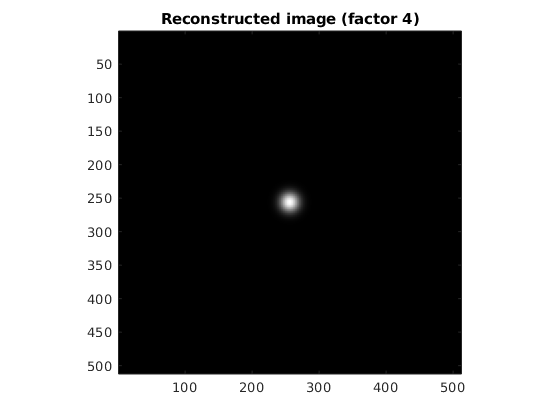

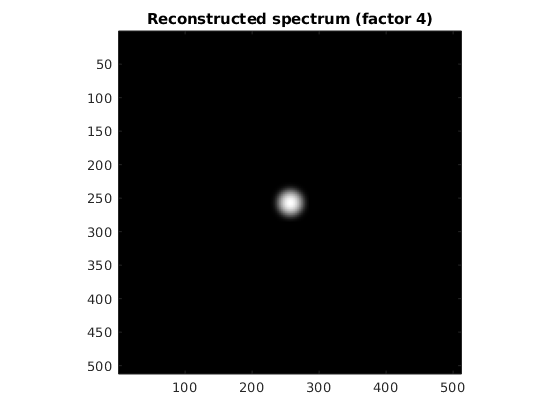


x0 = x;
for i=1:5
    
    T = 2^i; %sampling factor
    
    %sampling (take every T-th pixel of the image, other pixels are zero
    x = zeros(size(x));
    x(1:T:end, 1:T:end) = x0(1:T:end,1:T:end);
    
    %spectrum of sampled image
    X = fft2(x); 
     
    fig = fig+1; figure(fig); 
    imagesc(x); colormap gray; axis image; 
    title(sprintf('Sampled image (factor %i)',T))

    fig = fig+1; figure(fig);
    show_spectrum(X,'gray'); axis image; cl = get(gca, 'clim');
    title(sprintf('Magnitude spectrum of sampled image (factor %i)',T))
    
    %TODO {
    % - Implement the Shanon reconstruction filter. It is the square filter
    %   in the frequency domain with the spatial extent depending on the 
    %   highest frequency in the signal.
    % 
    %   S = ... (frequency domain filter of the same size as the spectrum)
    
    S = image_generator('square',size(X),30);
    
    
    figure(fig); hold on %Visualize the reconstruction filter extent
    tmp_x = find(sum(S,2)>0); 
    tmp_y = find(sum(S,1)>0); 
    plot([tmp_x(1),tmp_x(end),tmp_x(end),tmp_x(1),tmp_x(1)], ...
         [tmp_y(1),tmp_y(1),tmp_y(end),tmp_y(end),tmp_y(1)], 'r');
    hold off
    
    Xr = ifftshift(fftshift(X).*S); %Apply Shanon reconstruction filter to the sampled spectrum
    xr = real(ifft2(Xr)); %reconstruct the image using inverse FFT
             
    fig = fig+1; figure(fig);
    imagesc(xr); colormap gray; axis image;
    title(sprintf('Reconstructed image (factor %i)',T))
    
    fig = fig+1; figure(fig);
    show_spectrum(Xr,'gray',cl); axis image;
    title(sprintf('Reconstructed spectrum (factor %i)',T))
      
end

## Sampling theorem, aliasing, antialising filter (OPTIONAL)

We will (again) show what happens when you sample an image that contains high-frequencies so that the condition of the Sampling Theorem is violated. 

In case you are supposed to subsample an image by a given factor (e.g. 4 in this case), you need to apply a filter, "anti-aliasing" filter, that changes the spectrum of the input image to preserve the Sampling Theorem condition. 

Finally, compare the reconstructed images when the anti-aliasing filter is and is not used. Finally, see the effect of the anti-aliasing filter when the image is subsampled, i.e. sampled and reduced in size by the same factor. 

Important: Note that, when you see images in a Matlab window, they are usually sub-sampled based on the resolution of your screen. This may result in seeing aliasing effect, while the original image is aliasing free. To avoid this, maximize the window, zoom in, or save the image and see it in your favourite image presentation app in full resolution. 

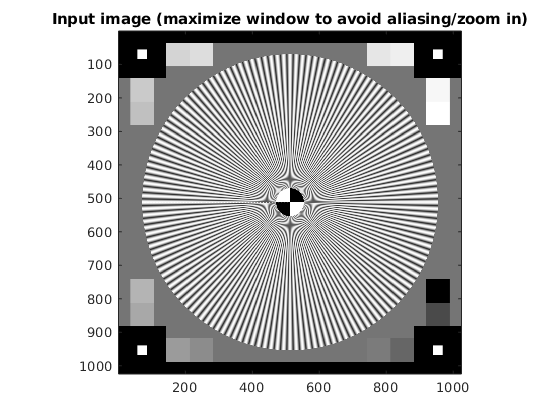

x = imread('star-chart.png'); %input image "focus pattern"
X = fft2(x);  %spectrum

T = 4; %sampling factor

fig=fig+1; figure(fig); imagesc(x); colormap gray; axis image
title('Input image (maximize window to avoid aliasing/zoom in)')

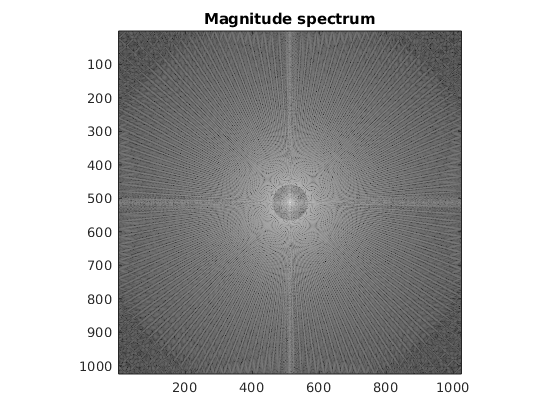

fig=fig+1; figure(fig); show_spectrum(X,'gray'); cl = get(gca, 'clim'); 
title('Magnitude spectrum')

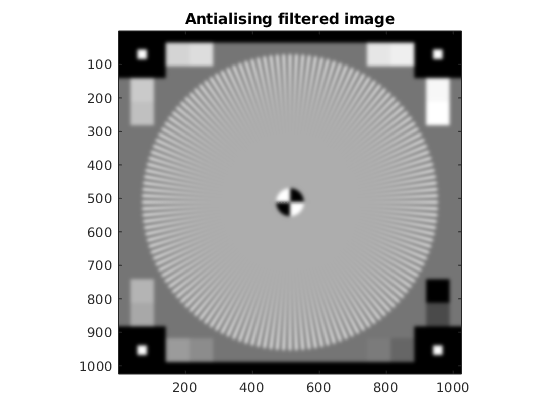


%TODO {
% - Implement the antialiasing filter. It will be a low-pass, namely a
%   Gaussian filter with a spatial extent set to preserve the condition of
%   the Sampling theorem. 
%
% A = ... (frequency domain filter of the same size as the spectrum)

A = image_generator('Gaussian',size(X),30);

X_blur = ifftshift(fftshift(X).*A);
x_blur = real(ifft2(X_blur)); 

fig=fig+1; figure; imagesc(x_blur); colormap gray; axis image
title('Antialising filtered image')

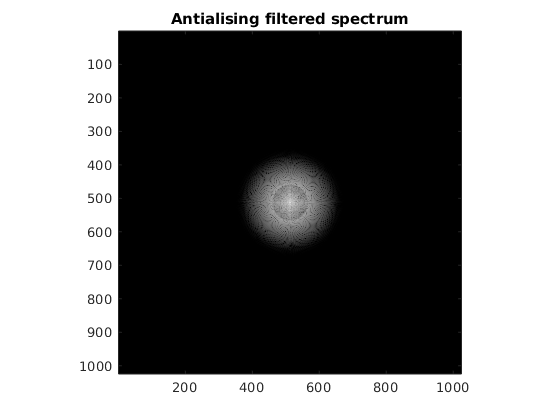


fig=fig+1; figure; show_spectrum(X_blur,'gray');
title('Antialising filtered spectrum');

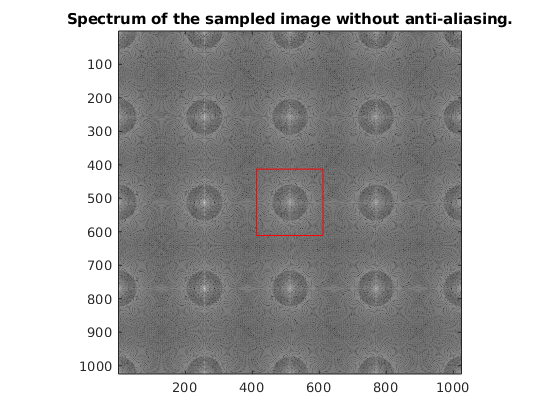

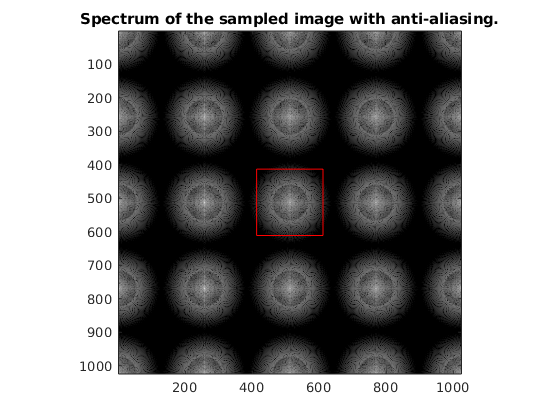


%sample without downsampling
x_sample = zeros(size(x));
x_sample(1:T:end, 1:T:end) = x(1:T:end, 1:T:end);

x_blur_sample = zeros(size(x));
x_blur_sample(1:T:end, 1:T:end) = x_blur(1:T:end, 1:T:end); 

%show spectrum of sampled signals
X_sample = fft2(x_sample); 
X_blur_sample = fft2(x_blur_sample); 

fig=fig+1; figure(fig); 
show_spectrum(X_sample,'gray',cl);
title('Spectrum of the sampled image without anti-aliasing.')

fig=fig+1; figure(fig); show_spectrum(X_blur_sample,'gray',cl);
title('Spectrum of the sampled image with anti-aliasing.')

%Shanon reconstruction of the sampled signal
%TODO {
%  - Use Shanon Reconstruction filter you have implemented in the previous
%    task.
%  S = ... (frequency domain filter of the same size as the spectrum)
%}

S = image_generator('square',size(X),100);

for f = [fig-1,fig] %Visualize the reconstruction filter extent
    figure(f); hold on 
    tmp_x = find(sum(S,2)>0);
    tmp_y = find(sum(S,1)>0);
    plot([tmp_x(1),tmp_x(end),tmp_x(end),tmp_x(1),tmp_x(1)], ...
        [tmp_y(1),tmp_y(1),tmp_y(end),tmp_y(end),tmp_y(1)], 'r');
    hold off
end

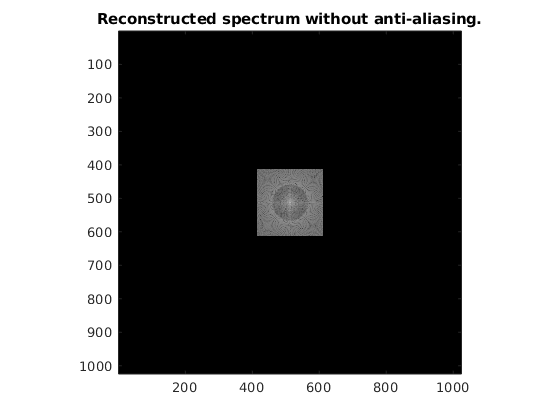

X_reconstr = ifftshift(fftshift(X_sample) .* S); 
X_blur_reconstr = ifftshift(fftshift(X_blur_sample) .* S); 

fig = fig+1; figure(fig); 
show_spectrum(X_reconstr,'gray',cl); 
title('Reconstructed spectrum without anti-aliasing.')

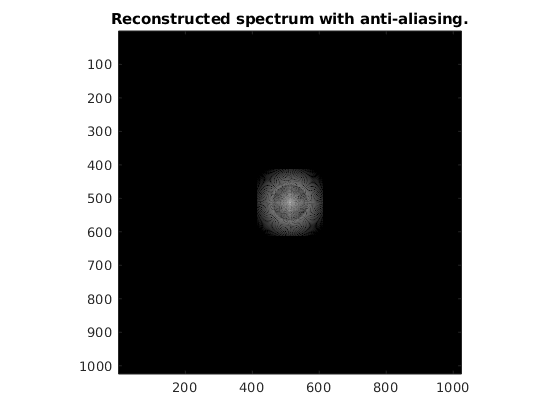


fig = fig+1; figure(fig); 
show_spectrum(X_blur_reconstr,'gray',cl); 
title('Reconstructed spectrum with anti-aliasing.')

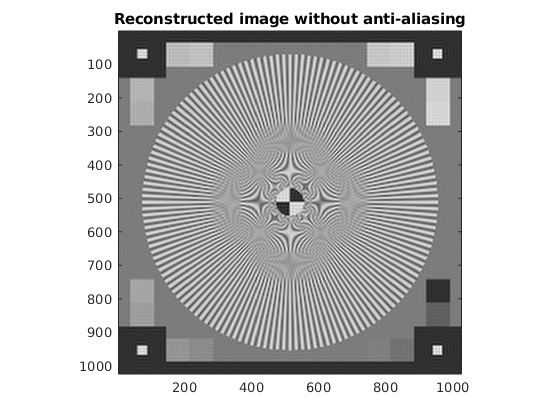


x_reconstr = real(ifft2(X_reconstr)); 
x_blur_reconstr = real(ifft2(X_blur_reconstr));

fig = fig+1; figure(fig);
imagesc(x_reconstr); colormap gray; axis image
title('Reconstructed image without anti-aliasing');

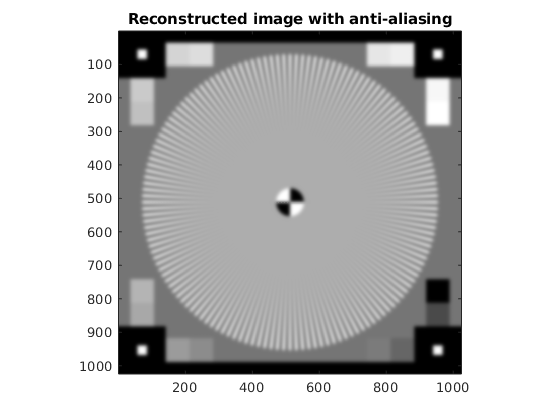


fig = fig+1; figure(fig);
imagesc(x_blur_reconstr); colormap gray; axis image
title('Reconstructed image with anti-aliasing')

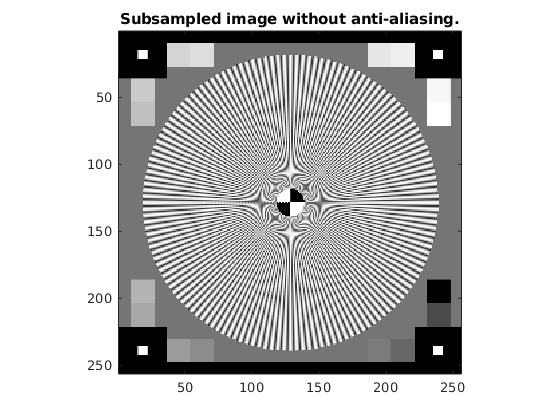


%Sub-sampled images (sampled + reduced in size)
fig = fig+1; figure(fig), 
imagesc(x(1:T:end, 1:T:end)); colormap gray; axis image
title('Subsampled image without anti-aliasing.');

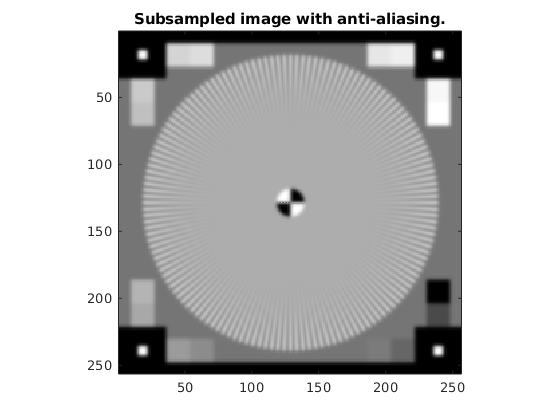


fig = fig+1; figure(fig), 
imagesc(x_blur(1:T:end, 1:T:end)); colormap gray; axis image
title('Subsampled image with anti-aliasing.');